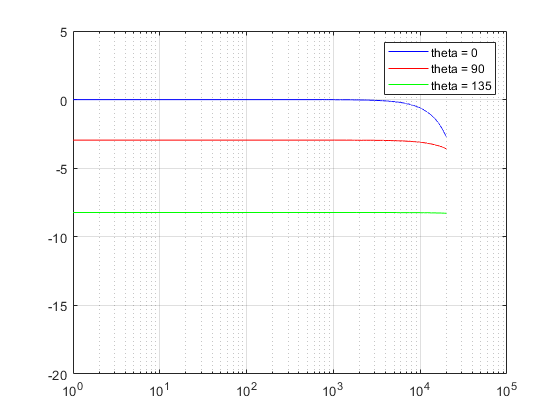

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% beampattern for first-order differential arrays
% 
% Created By Wang Wei
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
close all;

theta = linspace(0,2*pi,360);  % incident angle

f = 1:1:20000;                 % frequency

d = 0.005;                     % sensitive to beampattern
c = 345.8;
tao0 = d/c;                    % delay
omega = 2*pi*f;                % analog angle frequency

target = 0*pi/180;             % target direction
null = 180*pi/180;             % null direction

B = zeros(length(theta),length(f));
HL = zeros(1,length(f));
for i = 1:length(f)
    omega_k = omega(i);
    
    HL(i) = 1j/(omega(i)*tao0*(cos(null)-1));  % approximating e^x with 1+x
%     HL(i) = 1/(1-exp(1j*omega_k*tao0*(cos(null)-cos(target)))); % without approximating   
    for ang = 1:length(theta)
        % steering vector
        a = [1,exp(-1j*omega_k*tao0*cos(theta(ang)))];  % signal model,steering vector
        % filter weights
        H = [1;
            -exp(1j*omega_k*tao0*cos(null))];
        % beamforming
        B(ang,i) = a*H;              % without compensation filter
        B(ang,i) = B(ang,i)*HL(i);   % with compensation filter
        
%         B(ang,i) = 1/(1-cos(null))*(cos(theta(ang))-cos(null));   % with compensation filter
    end
end
figure,plot(pow2db(abs(B(1,:))),'b'),ylim([-20,5]),
set(gca,'XScale','log'),grid on
hold on
plot(pow2db(abs(B(90,:))),'r'),ylim([-20,5]),
hold on,
plot(pow2db(abs(B(135,:))),'g'),ylim([-20,5]),
legend('theta = 0','theta = 90','theta = 135');

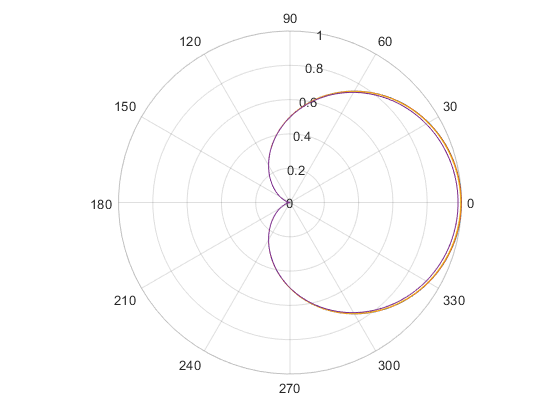


figure,polarplot(linspace(0,2*pi,360),abs(B(:,480)));
hold on,polarplot(linspace(0,2*pi,360),abs(B(:,960)));
hold on,polarplot(linspace(0,2*pi,360),abs(B(:,1920)));
hold on,polarplot(linspace(0,2*pi,360),abs(B(:,3840)));

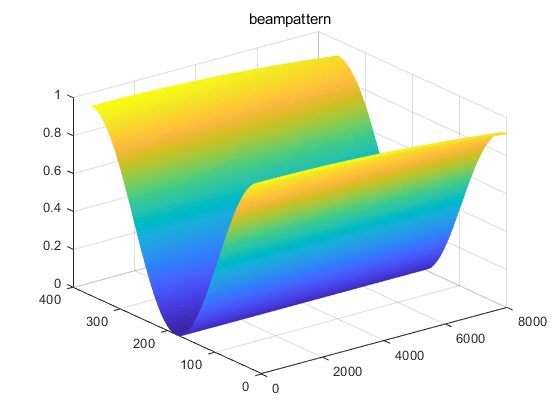


figure,mesh(abs(B(:,1:8000))),title('beampattern');